# Nonlinear Regression

© 2017 Griffin Chure. This work is licensed under a [Creative Commons Attribution License CC-BY 4.0](https://creativecommons.org/licenses/by/4.0/). All code contained herein is licensed under an [MIT license](https://opensource.org/licenses/MIT)

## In this tutorial...

In this tutorial, we will learn how to perform nonlinear regression using the $\chi^2$ statistic by estimating the DNA binding energy of the lacI repressor to the O2 operator DNA sequence. 

## What is probability?

One of the most powerful skills a scientist can possess is a knowledge of probability and statistics. I can nearly guarantee that regardless of discipline, you will have to perform a nonlinear regression and report the value of a parameter. Before we get into the details, let's briefly touch on what we mean we report the "value of a parameter".

What we seek to identify through parameter estimation is the value of a given parameter which **best describes the data under a given model**. Estimation of a parameter is intimately tied to our interpretation of probability of which there are two major schools of thought ([Frequentism](https://en.wikipedia.org/wiki/Frequentist_probability) and [Bayesian](https://en.wikipedia.org/wiki/Bayesian_probability)). A detailed discussion of these two interpretations is outside the scope of this tutorial, but see this [wonderful 25 minute video](https://www.youtube.com/watch?v=KhAUfqhLakw) on Bayesian vs Frequentist probability by [Jake VanderPlas](https://staff.washington.edu/jakevdp/). Also see [BE/Bi 103 - Data Analysis in the Biological Sciences](http://bebi103.caltech.edu/) by [Justin Bois](http://bois.caltech.edu/), which is one of the best courses I have ever taken.

How do we estimate a parameter?

Above, we defined a parameter value as that which best describes our data given a specific model, but what do we mean by "best describes"? Imagine we have some set of data ( $x$ and $y$, which are linearly correlated, as is shown in the figure below.

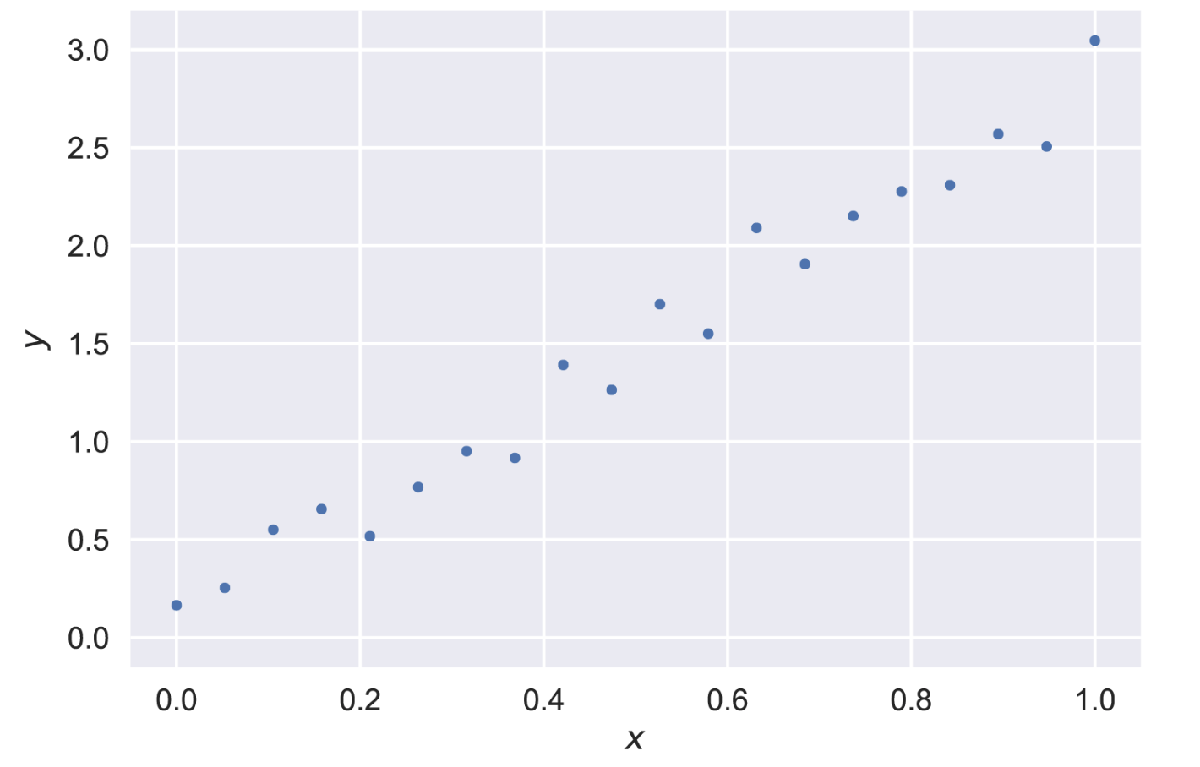

We can generate a model for this process of the form


$$y = \alpha x\ ,$$


where $\alpha$ is is the parameter we are interested in estimating. Our gut instinct is to say that the best estimate of α is the value in which the difference between each data point and the line resulting from our model is the smallest. This value is called the **residual**.

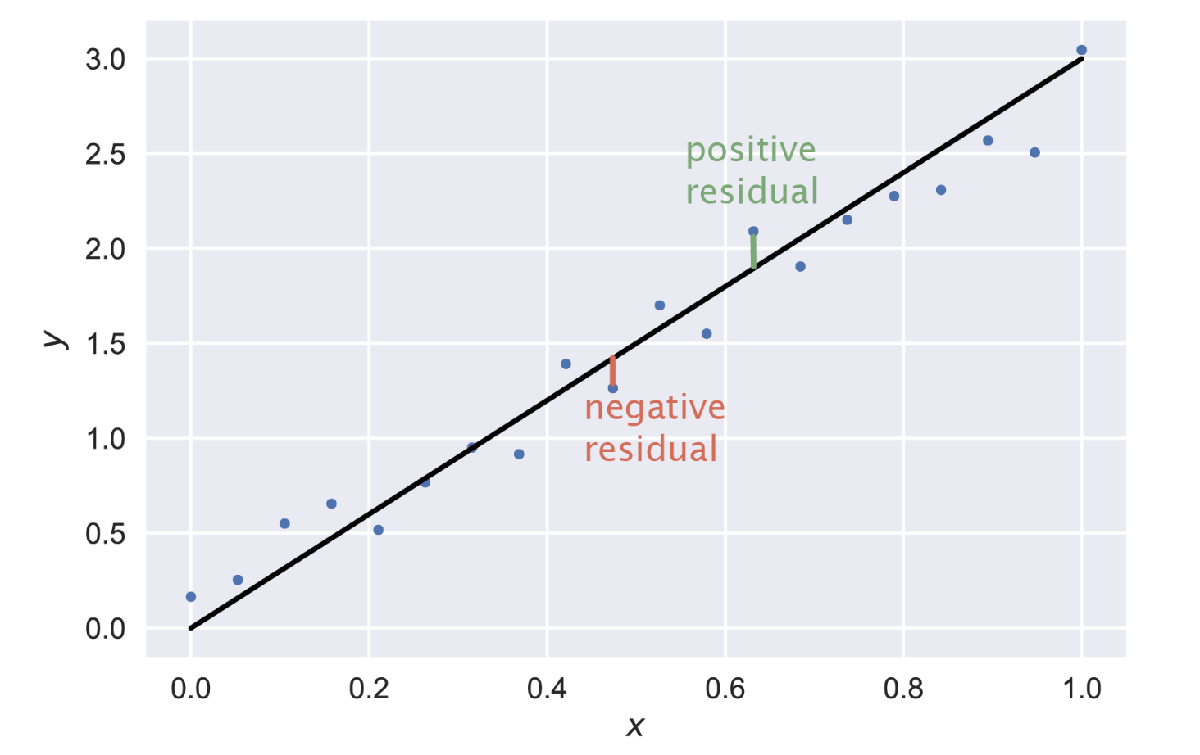

We can assume that the noise in our data is Gaussian distributed about this model, meaning that we are assuming there are no outliers. Under this assumption, we can compute the sum of the squares of the residuals of all the data points for a range of values of α. This is called the Chi-squared statistic,


$$\chi^2 = \sum\limits_{i} {(y_i - y(\alpha))^2 \over \sigma_i^2}$$


where $y_i$ is the $i^{th}$data point, $y(\alpha)$ is the predcted value of $y$ using a given value of $\alpha$, and $\sigma_i^2$ is the variance of the datum. The value of $\alpha$ which minimizes $\chi^2$ is deemed the "best-fit" parameter value.

In the following section, we will use this method of non-linear regression to infer the DNA binding energy of the LacI repressor to the DNA

## The Data Set

As an example, we will use the data from [Hernan Garcia and Rob Phillips' 2011 paper](http://www.pnas.org/content/108/29/12173.abstract) *Quantitative dissection of the simple repression input-output function*. In this paper, Hernan  and Rob developed a statistical mechanical model of gene regulation. I won't go into the details of the derivation in this tutorial, but when the dust settles, we are left with a beautifully simple expression that summarizes the fold-change in gene expression, 


$$\text{fold-change} = \left(1 + {R \over N_{NS}}e^{-\Delta\varepsilon_{r} / k_BT}\right)^{-1}\ ,$$


where $R$ is the number of repressors per cell, $N_{NS}$ is the number of non-specific binding sites available for the repressor, $k_BT$ is the thermal energy of the system, and $\Delta\varepsilon_r$ is the binding energy of the repressor, which is the parameter we would like to estimate. Hernan set up these experiments  by generating a simple repression construct in which the expression of a lacZ enzyme was regulated by the lacI repressor binding to a single binding site directly upstream of the transcription start site. 

He quantified the number of repressors per cell $R$ through (a lot) of quantitative Western blotting. This allowed him to make very specific measurements of the fold-change quantity to test this theory. We'll use all of his data from this paper to estimate the binding energy of the three native *lac* operon operators $-$ O1, O2, and O3. 

The data set can be [downloaded from the course website](http://www.rpgroup.caltech.edu/courses/bi1_2017/data/lacZ_titration_data.csv). To begin, we'll load in this file using the MATLAB function `readtable`.

% Load in the 2011 Garcia data
data = readtable('data/lacZ_titration_data.csv')

data =     repressor    fold_change    operator
    _________    ___________    ________

    22.42         0.1756        'O2'    
    59.34        0.04519        'O2'    
      124        0.02151        'O2'    
    255.3        0.01241        'O2'    


Here, we can see that we have four data points in this file. We have cells with a range of average repressor copy  number, the fold-change in gene expression, and the respective operator identity 'O2'.  Let's plot the fold-change as  a function of repressor copy number to get a feeling for the behavior of the data. 

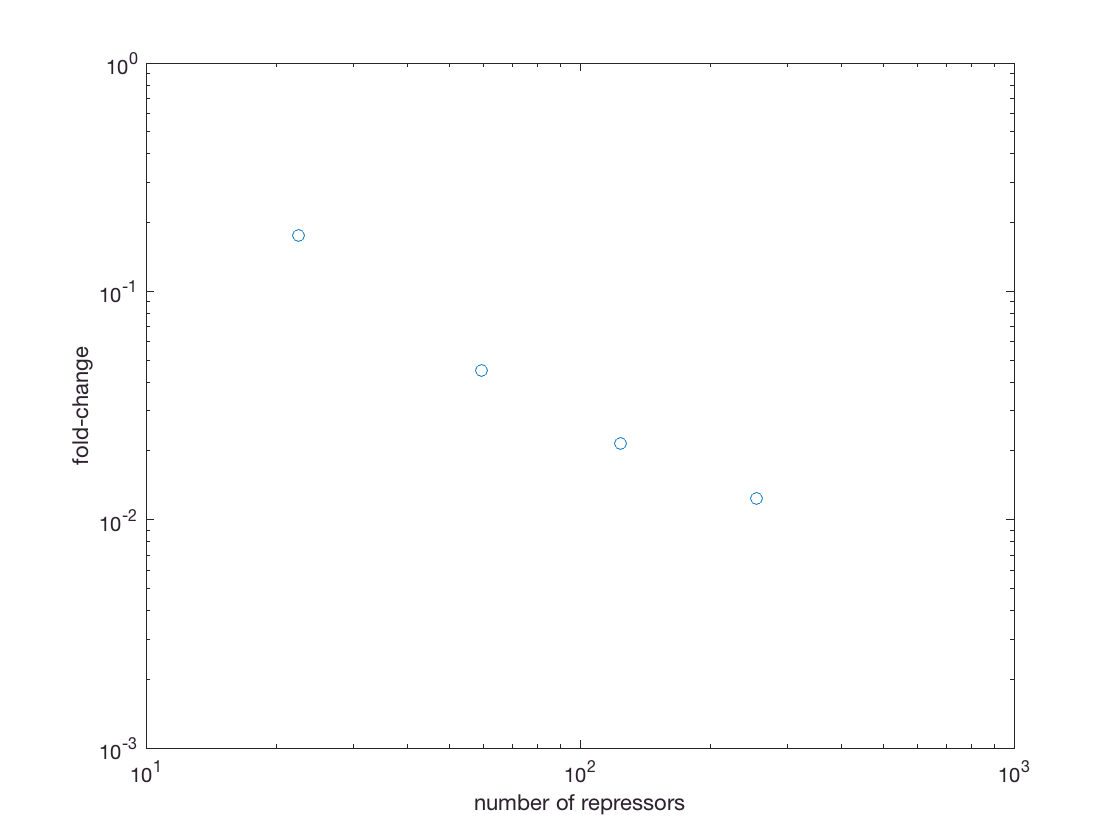

% Plot the repressor copy number vs the fold_change
loglog(data.repressor, data.fold_change, 'o')
xlabel('number of repressors')
ylabel('fold-change')

% Show the full limits of the fold-change. 
ylim([1E-3, 1])

Now, a good fit would be a value of $\Delta\varepsilon_r$ that minimizes the difference between the prediction and the measured fold-change data. To get a "by-eye" estimate of the binding energy, we are going set up a vector spanning a large range of these energies and evaluate the $\chi^2$ statistic at each energy value. We can use our biological intuition to pick some bounds that are sensical. For example, we **know** that the repressor binds the DNA with some affinity. That means that it must have some binding energy $>0$. Likewise, we **know** that the binding of the repressor to the DNA is not covalent, so it should be weaker than that energy scale. The strongest known non-covalent bond is  between [streptavidin and biotin](https://en.wikipedia.org/wiki/Streptavidin) with a dissociation constant $K_D$ of $~1 \times 10^{-15}M$. We can convert this to an energy in units of $k_BT$ by


$$E_\mathrm{biotin-strepavidin}  = k_BT\log\left({K_D \over C_0}\right) = k_BT \log\left({1\times10^{-15}\ \mathrm{M} \over 1\ \mathrm{M}}\right) \approx -30\ k_BT\ ,$$


where $C_0$ is a reference concentration of $1\ \mathrm{M}$.  Using these bounds of $\Delta \varepsilon_r \in (-30\ k_BT, 0\ k_BT]$, we can perform the regression!

% Set up the range of binding energies to look at. 
epRange = linspace(-30, 0, 500);

% Extract the repressors and the fold-change values from the data.
repressors = data.repressor;
foldChange = data.fold_change;

% Loop through each energy and compute the chi squared. 
for ep=1:length(epRange)
    % Compute the theoretical value. 
    theo = (1 + (repressors / 5E6) * exp(-epRange(ep))).^-1;
    
    % Compute the chisquared from the data and store it. 
    chiSq(ep) = sum((theo - foldChange).^2);
end

Now, let's plot the $\chi^2$ value for each value of the binding energy $\Delta \varepsilon_r$ that we computed. 

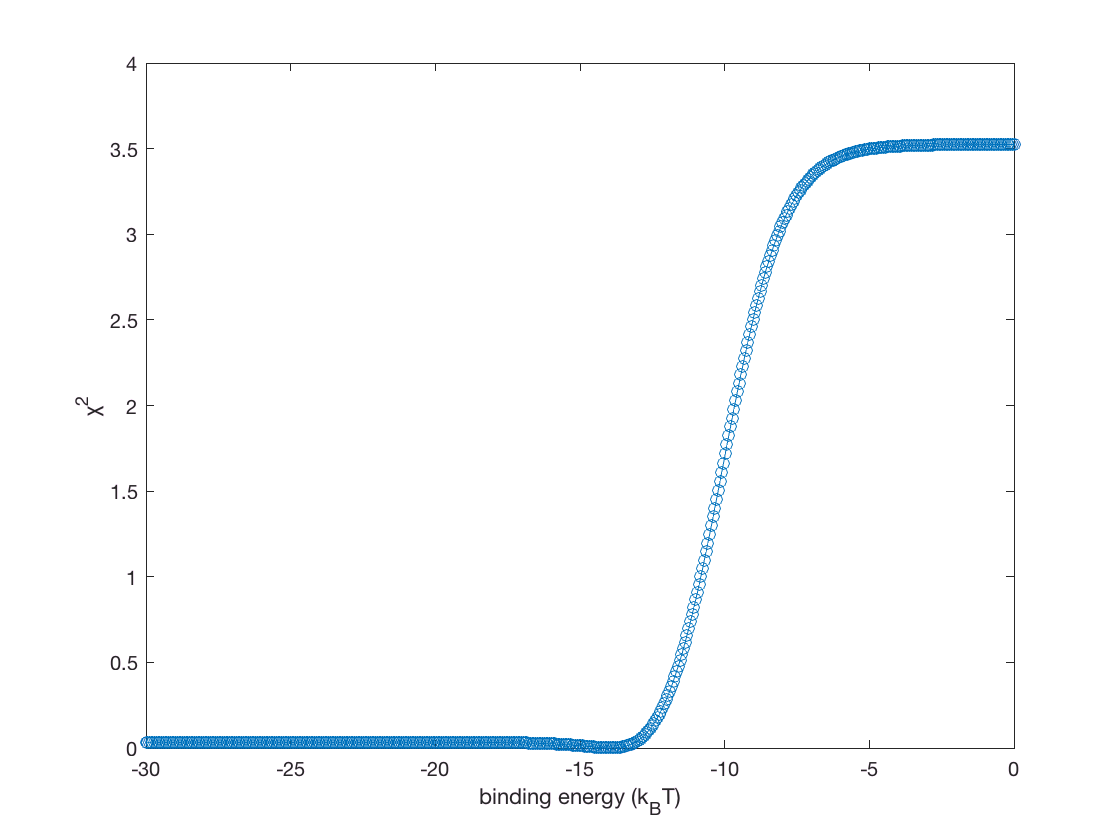

plot(epRange, chiSq, '-o')
xlabel('binding energy (k_BT)')
ylabel('χ^2')

Wow! The $\chi^2$ statistic blows up after around -12 or -13 $k_BT$. To get a better sense of where the minimum is, we can plot this with a log scale on the $y$-axis since this is covering several orders of magnitude. 

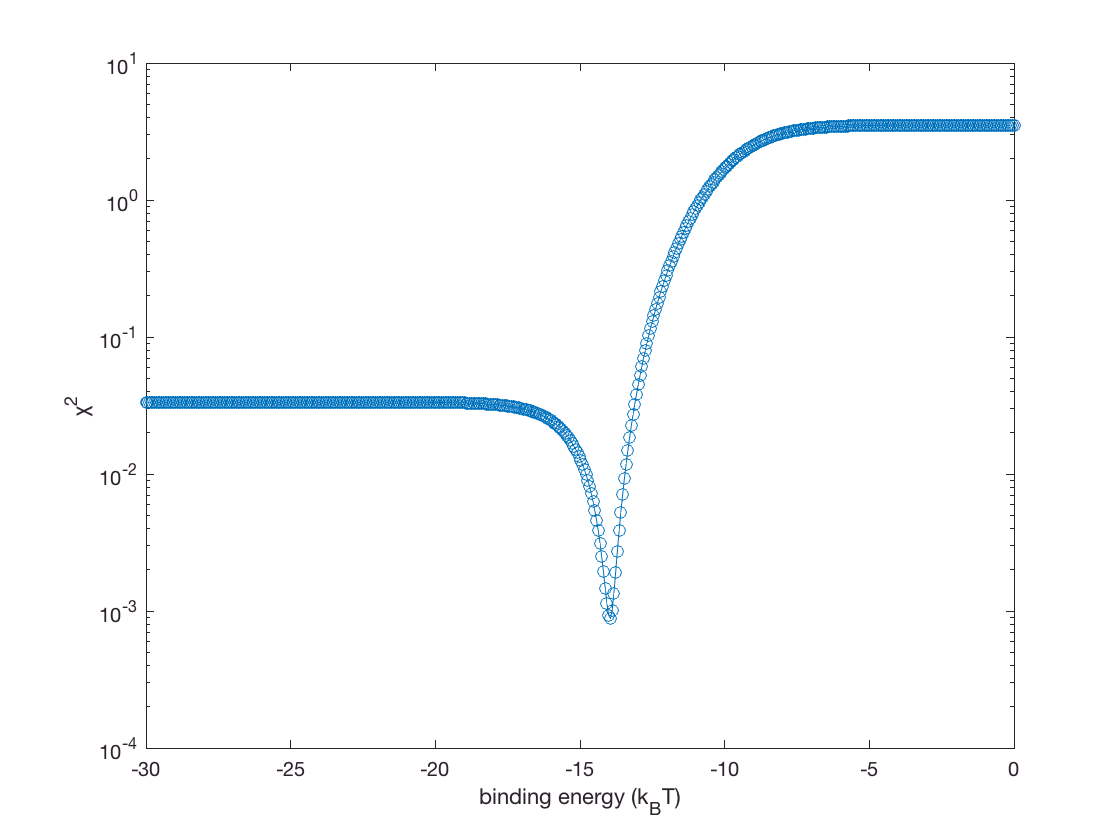

% Plot it with semilogy
semilogy(epRange, chiSq, '-o')
xlabel('binding energy (k_BT)')
ylabel('χ^2')

There's the minimum! Remember, the smaller the sum of the squares of the residuals, the better the fit. By zooming in to the plot above, it looks like the minimum is right around ~ $-14\ k_BT$ Let's plot two examples of "bad" fits along with this value and see how well it matches the data. 

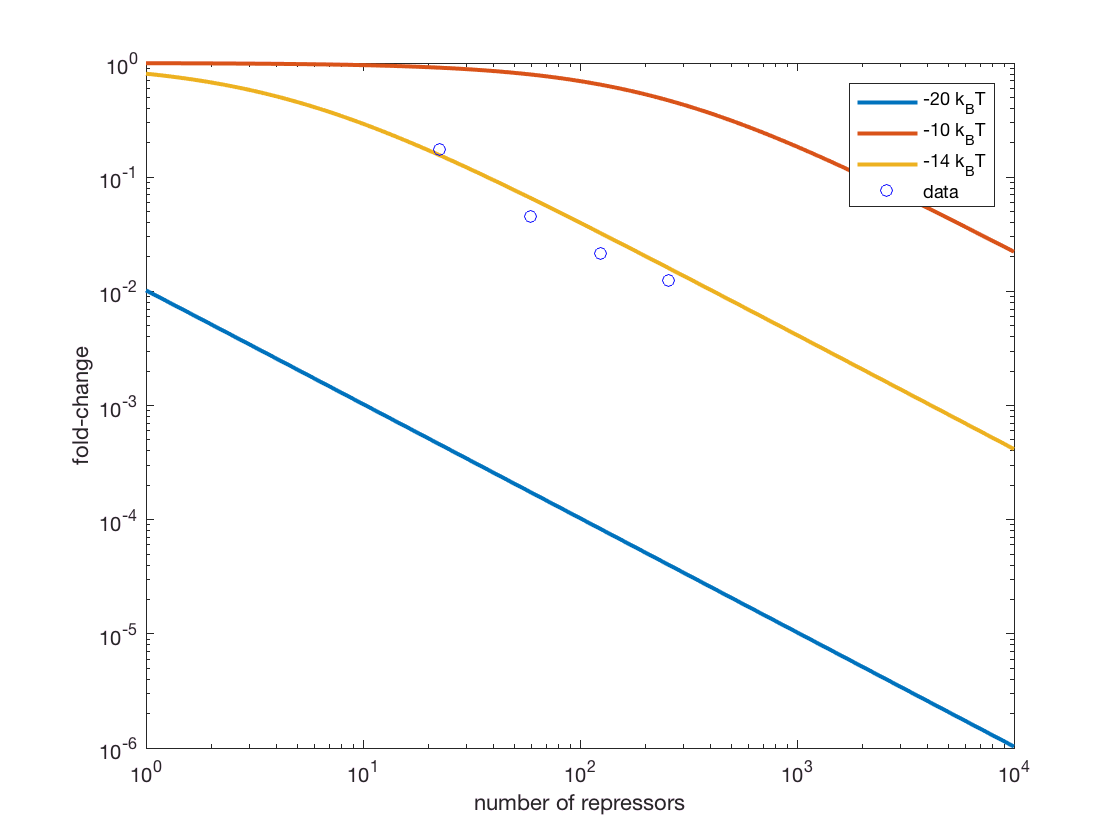

% Pick two values of a "bad" fit. 
badEp1 = -20; % in units of k_BT
badEp2 = -10; % in units of k_BT

% Now define our best fit. 
bestEp = -14; % in units of k_BT. 

epValues = [badEp1, badEp2, bestEp];
% Now compute the curves for these fits. 
repRange = logspace(0, 4, 500);

for i=1:length(epValues)
    fit = (1 + (repRange ./ 5E6) * exp(-epValues(i))).^-1;
    
    % Plot the fits. 
    loglog(repRange, fit, '-', 'LineWidth', 2, 'DisplayName', [num2str(epValues(i)), ' k_BT']);
    hold on
end

% Now plot the experimental data. 
loglog(repressors, foldChange, 'bo', 'DisplayName', 'data');

% Now add a legend
legend('-DynamicLegend');

% And of course, some labels. 
xlabel('number of repressors')
ylabel('fold-change')
hold off;

That looks pretty good! We can see that the binding energy $\Delta \varepsilon_r = -14 \ k_BT$gives a very nice fit while the others are quite a bit off (afterall, we expected them to be bad!).  

While that more-or-less covers how a sum-squares minimizer works, this is **not** how you should be fitting data in your daily life. 

## How you *should* be fitting your data

In the above example, we went through  and set up an array of $\Delta \varepsilon_r$ values to compute the $\chi^2$ statistic over. By zooming in on the minimum, we were able to pick a value **by hand** that seemed to be the minimum. However, we only computed the $\chi^2$ over a range of values that we specifically wrote out using the `linspace` function! This means that if were were to choose more points, the values that our algorithm would calculate over would increas and threfore give us an even more precise measurement of the best fit value. Obvioulsy, this introduces some degree of bias into your analysis that you (hopefully) don't want! Furthermore, we did this analysis by trying to fit only **one** parameter of a very well-behaved function. If we had two parameters we wanted to estimate (such as $R$ and $\Delta \varepsilon_r$), this becomes much more difficult to compute and the function may have multiple minima which produce the same fit. 

For these reasons, it's better to use a more complicated algorithm to determine these values. Perhaps the most common nonlinear regression algorithm used is the [Levenberg-Marquardt algorithm](https://en.wikipedia.org/wiki/Levenberg–Marquardt_algorithm) which takes a very interesting approach. This algorithm identifies a local minimum in the $\chi^2$ given an initial guess value. It will then go through another round of this local minimum detection until a stopping criterion is satisfied. If you're interested in the details of this optimization procedure, see [this set of notes](http://people.duke.edu/~hpgavin/ce281/lm.pdf) from Henry P. Gavin at Duke University.

In MATLAB, the `lsqnonlin` function uses *essentially* this algorithm with a few kinks. To use this function, we will have to define a function called `residFunc` which computes the difference between our theoretical prediction and our data. Unfortuantely, functions in MATLAB need to be their own file. Instead of writing this different file, I'm going to define something called an *anonymous function* which is essentially a one-line function. If you are interested, come talk to me privately or send  me an email (`gchure@caltech.edu`) and we can go over it. 

% Define the anonymous function
residFunc = @(epVal) (sum((foldChange - (1 + (repressors ./ 5E6)*exp(-epVal)).^-1).^2));

Now we can just call the `residFunc` function within the MATLAB `lsqnonlin` to determine a better estimate of the best binding energy value.

%Use the lsqnonlin function. 
funcEp = lsqnonlin(residFunc,-14)


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



funcEp = -13.9679

And there we go! It looks like our guess of $-14\ k_BT$ was pretty close! Let's go ahead and plot the result from this fitting ontop of our best fit "by-eye" estimate. 

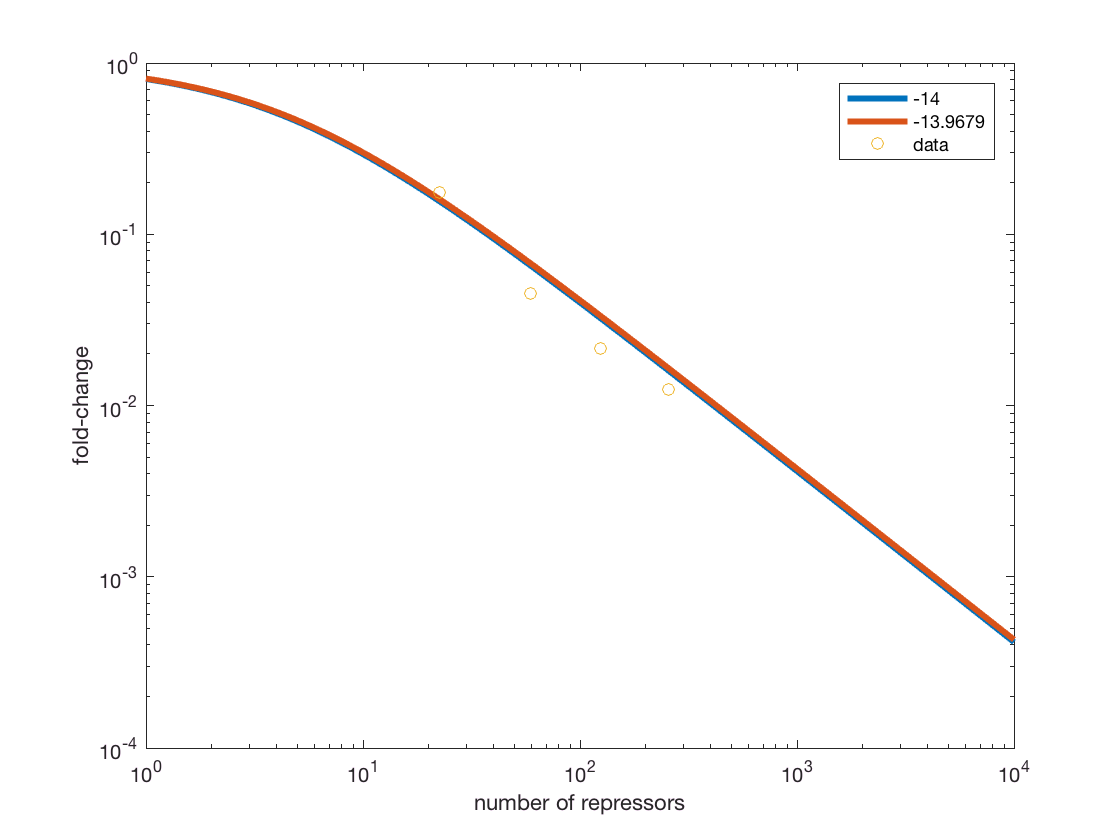

% Compute the fold-change using the best fit and the funcFit value.
eps = [bestEp, funcEp];
for ep=1:length(eps)
    theo = (1 + (repRange / 5E6) * exp(-eps(ep))).^-1;
    loglog(repRange, theo, '-', 'DisplayName', num2str(eps(ep)), 'LineWidth', 3);
    hold on;
end

% Now plot the data. 
loglog(repressors, foldChange, 'o', 'DisplayName', 'data');

% Add a legend and labels. 
legend('-DynamicLegend');
xlabel('number of repressors');
ylabel('fold-change');
hold off 

As expected, there is very little difference in our fit, but it is still better to use the well tested algorithms packaged with MATLAB. 

## In conclusion...

In this tutorial, we learned what it means to report a parameter value, a simple scheme for estimating parameter values, and some interesting information about how tightly a lacI repressor binds DNA. While plotting the $\chi^2$ statistic is useful pedagogically, this becomes far more complicated if you are fitting more than one parameter. Furthermore, your model of interest may have many *local* minima that you may misidentify as the best-fit parameter value. When you inevitably do regression in your "real-life" research, you should be aware of these issues and use an appropriate algorithm.